### Problem Definition

Given a set of assets corresponding to expected returns and covariances, along with a risk factor and budget, we seek a subset of assets such that the resulting weighted mean-variance is maximized. 

% Covariance between assets
sigma = [ 0.0064 0.00408 0.00192 0;
    0.00408 0.0289 0.0204 0.0119;
    0.00192 0.0204 0.0576 0.0336;
    0 0.0119 0.0336 0.1225 ];

% Expected returns for assets
mu = [0.05; 0.1; 0.12; 0.18];

% Risk appetite
q = 0.5;

% Budget
B = 3;

% Penality for budget
lambda = 10;

% Number of variables 
N = size(sigma, 1);

### **Classical Solution with QUBO **

The mean-variance portfolio objective has the quadratic term Q, linear term c, no constant term, and is constrained on the budget B with penalty lambda. This is reformulated into a Quadratic Unconstrained Binary Optimization (QUBO) problem. See [https://www.mathworks.com/help/matlab/math/qubo-constraints.html](https://www.mathworks.com/help/matlab/math/qubo-constraints.html) for how constraints can be added to QUBO problems.

Q = q.*sigma;
c = mu;

qprob = qubo(Q + lambda*ones(size(Q)), -(c + (2*lambda*B*ones(N,1))), lambda*B^2);

sol = solve(qprob);
sol.BestX

ans =      1
     1
     0
     1


sol.BestFunctionValue

ans = -0.2351

### **Quantum Solution with VQE-CVaR **

To reduce compilation overhead, an ansatz is used that respects the native gate set and connectivity of the Aspen-M-3 device. 

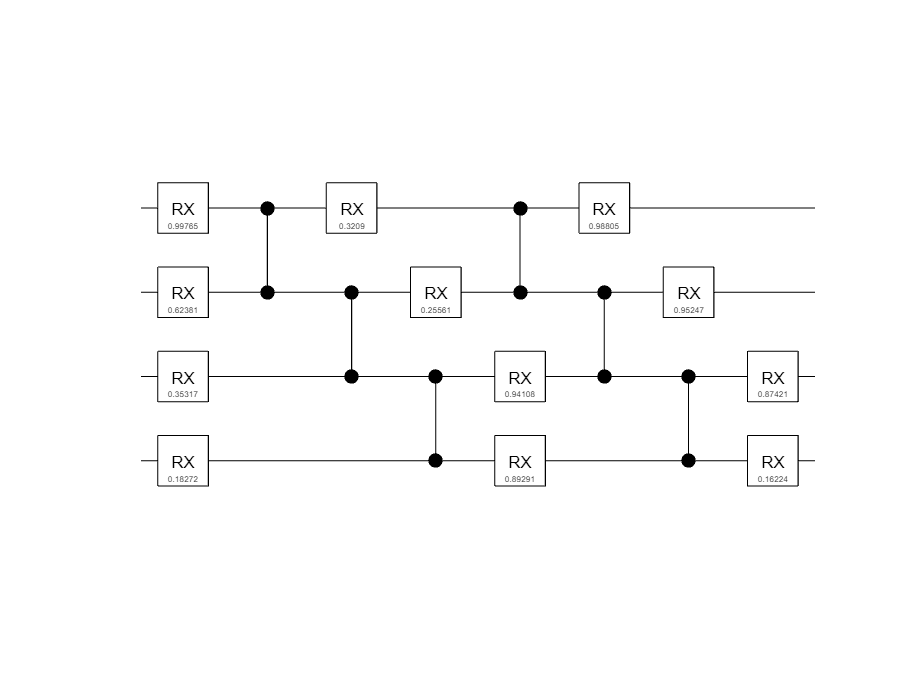

numQubits = qprob.NumVariables;

% Number of repeated entangling blocks
ansatzDepth = 2;

% Number of learnable angles for the ansatz circuit
numAngles = numQubits*(ansatzDepth+1);

% Plot the ansatz with arbitrary angles to view its structure
randAnsatz = buildAnsatz(rand(numAngles, 1), numQubits);
plot(randAnsatz)

#### **Simulate the Variational Quantum Eigensolver **

The objective function for the optimizer takes the angles and simulates an iteration of the VQE-CVaR routine. 

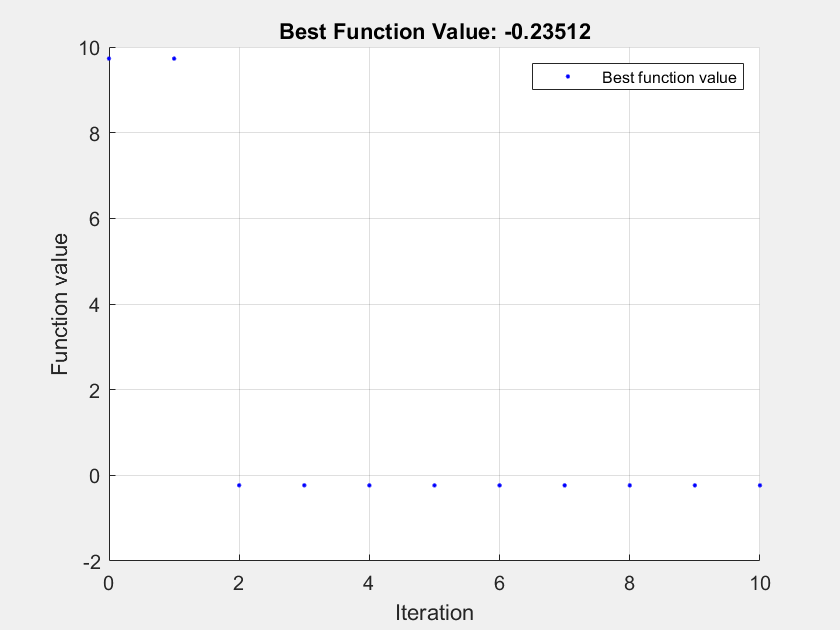

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


objFcn = @(theta) simVQECVAR(theta, qprob);

options = optimoptions("surrogateopt", "MaxFunctionEvaluations",10);

lb = repmat(-pi, numAngles, 1); 
ub = repmat(pi, numAngles, 1);
[optAngles, ~] = surrogateopt(objFcn,lb,ub,[],[],[],[],[],options);

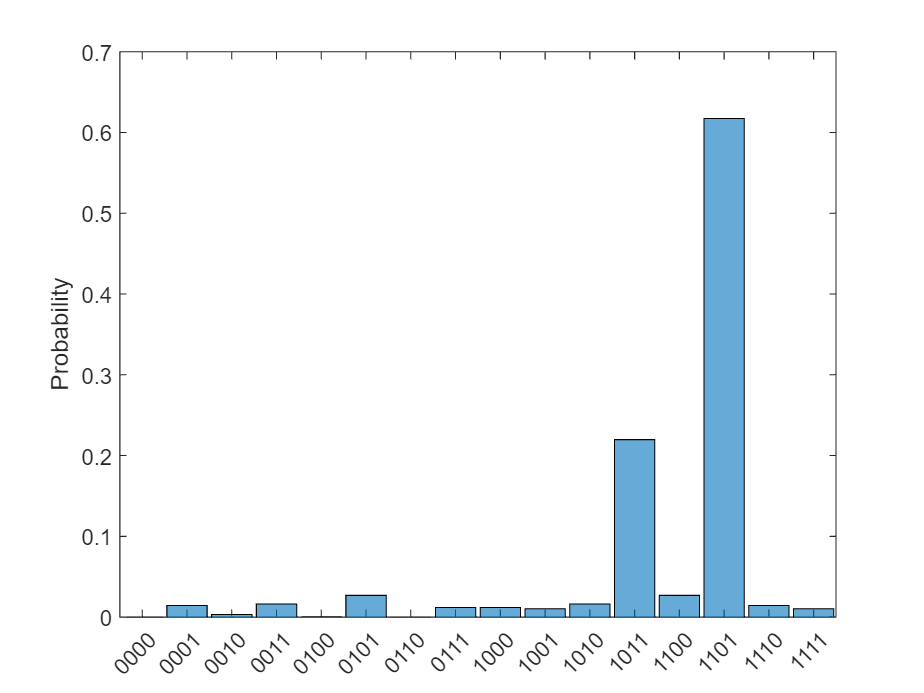

optAnsatz = buildAnsatz(optAngles, numQubits);
sv = simulate(optAnsatz);
figure
histogram(sv)

#### Run the Final Circuit on Hardware

Run the optimized ansatz circuit on the Aspen-M-3 device provided through AWS Braket.

device = quantum.backend.QuantumDeviceAWS("Aspen-M-3");
task = run(optAnsatz, device, NumShots=100);
wait(task)
result = fetchOutput(task);
histogram(result)

function ansatz = buildAnsatz(angles, numQubits)

% Linear pattern
entgBlk = czGate(1:numQubits-1, 2:numQubits);

angles = reshape(angles, numQubits, []);

% Assemble alternating layers of rotations and entangling blocks
gates = rxGate(1:numQubits, angles(:,1));
for p = 2:size(angles, 2)
gates = [gates; entgBlk; rxGate(1:numQubits, angles(:,p))];
end
ansatz = quantumCircuit(gates);
end


function value = simVQECVAR(angles, QUBO)  

% Construct and simulate the variational circuit 
ansatz = buildAnsatz(angles, QUBO.NumVariables);
qState = simulate(ansatz);

% Sample and query the state probabilities
numSimShots = 1000; 
qMeasurement = randsample(qState, numSimShots);
[states, probs] = querystates(qMeasurement);

% Sort the probabilities by the evaluated objective 
x = double(char(states)=='1')';
[values,sortperm] = sort(evaluateObjective(QUBO,x));
probs = probs(sortperm);

% CVaR cutoff 
alpha = 0.1;

% Compute CVaR over the low tail of the distribution
cutoff = nnz(cumsum(probs) < alpha);
cvarProbs = probs(1:cutoff);
cvarProbs(end+1) = alpha - sum(cvarProbs);
value = dot(cvarProbs, values(1:cutoff+1))/alpha;

end